# 大滞后过程采样控制仿真

被控对象传递函数：$G_s=\frac{K}{T\cdot s +1} e^{-\tau_0 s$，$K=10,T=5,\tau_0=2$，请在同一个plot图中绘制采样周期（采样控制间隔）$T_s=0.1,1,1.5,2.5$四种情况下的闭环采样控制响应曲线

K=10;
T=6;
tau0=2;
s=tf('s');
Ts_list=[1.5,1.8,2.2,2.5];
Gs=K/(T*s+1)*exp(-tau0*s)

Gs =
 
                10
  exp(-2*s) * -------
              6 s + 1
 
Continuous-time transfer function.



Gs=ss(Gs);

## 采样控制效果

不同采样周期使用不同的控制器

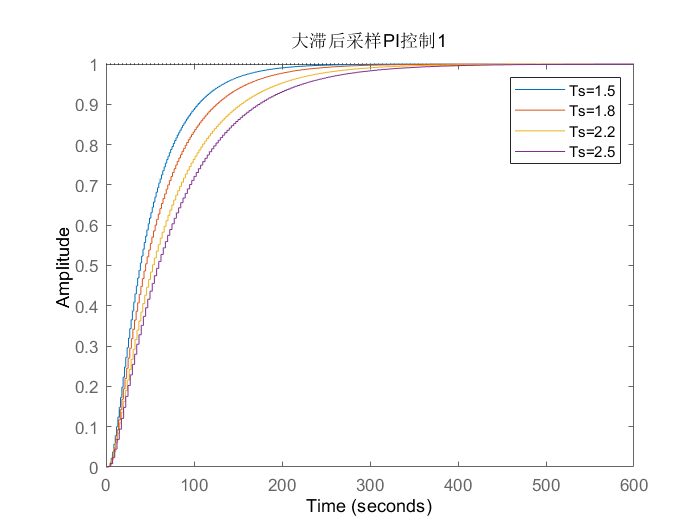

figure();
hold on;
for Ts=Ts_list
    Gz=c2d(Gs,Ts,'zoh');
    Gc=pidtune(Gz,'PI');
    Phi=feedback(series(Gc,Gz),1);
    Phi.Name="Ts="+Ts;
    stepplot(Phi);
end
legend;hold off;
title("大滞后采样PI控制1")

不同采样周期使用相同控制器

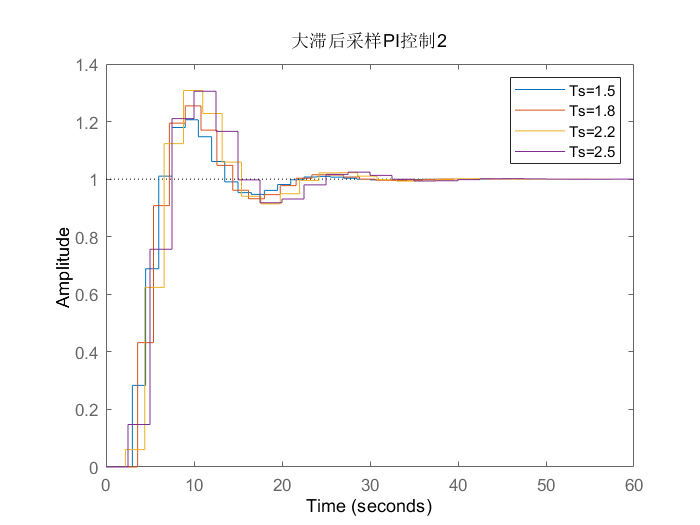

figure();
hold on;
Gcs=pidtune(Gs,"PID");
for Ts=Ts_list
    Gz=c2d(Gs,Ts,'zoh');
    Gcz=c2d(Gcs,Ts);
    Phi=feedback(series(Gcz,Gz),1);
    Phi.Name="Ts="+Ts;
    stepplot(Phi);
end
legend;hold off;
title("大滞后采样PI控制2")

## Simulink

不同采样周期使用不同控制器

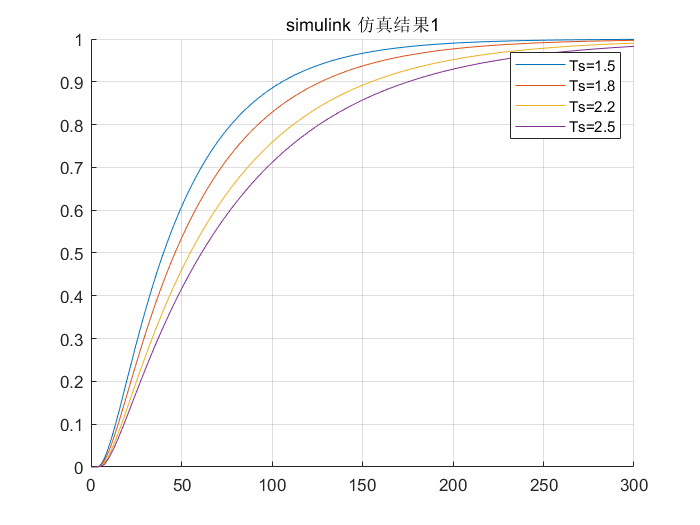

figure();
hold on;
for Ts=Ts_list
    Gz=c2d(Gs,Ts,'zoh');
    Gc=pidtune(Gz,'PI');
    Name="Ts="+Ts;
    %run simulink
    simOut = sim('sampleControl.slx','SaveOutput','on','OutputSaveName','yout','SaveFormat', 'Dataset');
    %get data
    outputs = simOut.get('yout');
    y = (outputs.get('y').Values);
    plot(y,'displayName',Name);
end
legend;hold off;grid on;
title('simulink 仿真结果1')

不同采样周期使用相同控制器

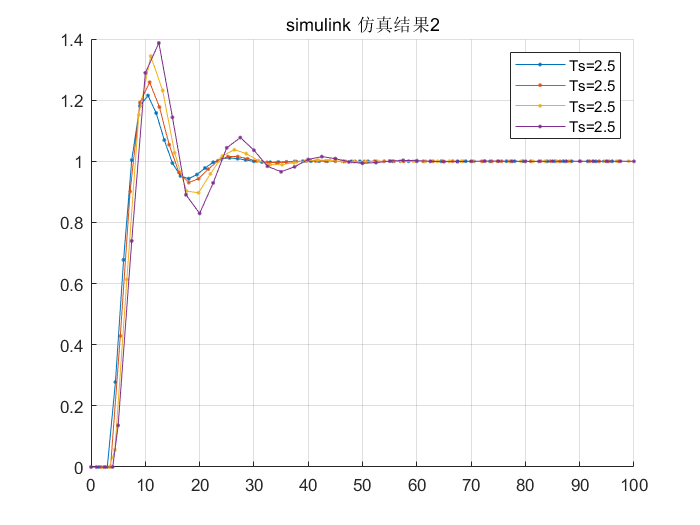

figure();
hold on;
Gcs=pidtune(Gs,"PID");
for Ts=Ts_list
    Gz=c2d(Gs,Ts,'zoh');
    Gc=c2d(Gcs,Ts);
    %run simulink
    simOut = sim('sampleControl.slx','SaveOutput','on','OutputSaveName','yout','SaveFormat', 'Dataset');
    %get data
    outputs = simOut.get('yout');
    y = (outputs.get('y').Values);
    plot(y,'.-','displayName',Name);
end
legend;hold off;grid on;
xlim([0,100])
title('simulink 仿真结果2')